**Name : Krish Singh**

**Roll: AID25072**

**AID Semester 2**

## **LAB EXCERCISE 6**

**1. Generate a sample of 2000 numbers from a standard normal population using Box-Muller’s method and draw the histogram. **

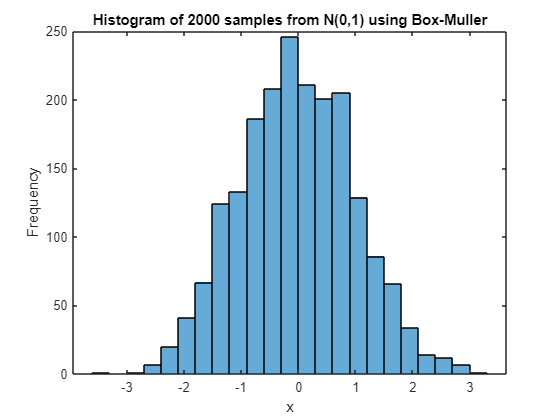

u1=rand(1000,1);
u2=rand(1000,1);
r=-2*log(u1);
theta=2*pi*u2;
x1=sqrt(r).*cos(theta);
x2=sqrt(r).*sin(theta);
x=[x1;x2];
histogram(x);
title('Histogram of 2000 samples from N(0,1) using Box-Muller');
xlabel('x');
ylabel('Frequency')

2. Generate a sample of 100 normally distributed numbers with mean 55 and standard deviation 10 using Box-Muller’s formula and draw the histogram. 

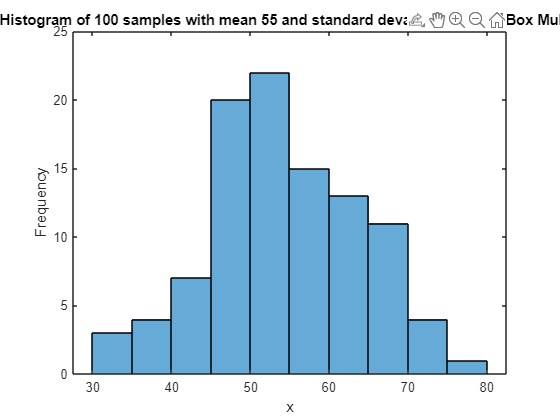

mean=55;
std=10;
u1=rand(50,1);
u2=rand(50,1);
r=-2*log(u1);
theta=2*pi*u2;
x1=mean+std*(sqrt(r).*cos(theta));
x2=mean+std*(sqrt(r).*sin(theta));
x=[x1;x2];
histogram(x)
title("Histogram of 100 samples with mean 55 and standard devation 10 using Box Muller");
xlabel('x')
ylabel('Frequency')

3. Generate 1200 numbers from a standard normal population, directly using the MATLAB command, ‘randn’. 

(a) Draw a histogram and check if the curve is bell shape.

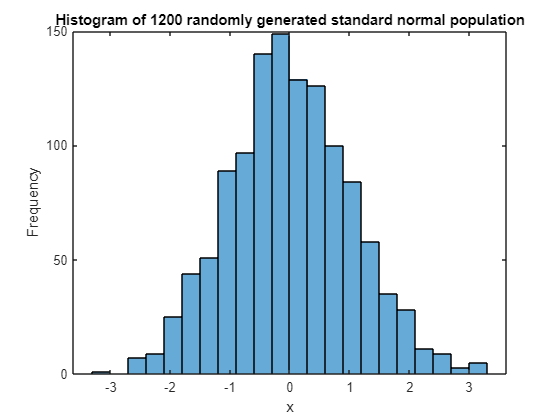

x=randn(1200,1);
histogram(x);
title('Histogram of 1200 randomly generated standard normal population')
xlabel('x')
ylabel('Frequency')

(b) Find the mean and variance of the sample drawn and compare it with the mean and variance of the population. 

samplemean=mean(x)

samplemean = 0.0150

variance=var(x)

variance = 1.0446

4. Generate 500 numbers from a normal population with mean 300 and variance 50, using ‘randn’ command. 

(a) Draw a histogram with 20 bins. 

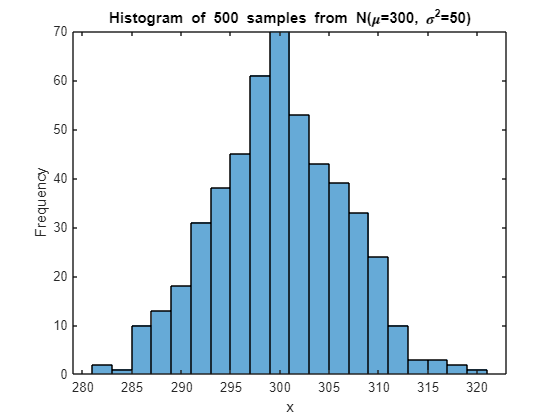

meanv=300;
std=sqrt(50);
u=randn(500,1);
x=meanv+std*u;
histogram(x,20);
title('Histogram of 500 samples from N(\mu=300, \sigma^2=50)');
xlabel('x');
ylabel('Frequency');

(b) Find the mean and variance of the sample and compare with that of the population . 

clear mean;
meanp=mean(x)

meanp = 299.9623

variance=var(x)

variance = 43.1300

(c) Plot the pdf of the normal distribution. 

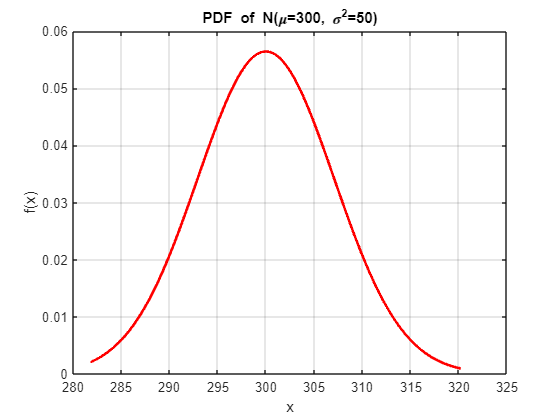

x_range=linspace(min(x),max(x),1000);
pdfval=pdf('norm',x_range,meanv,std);
plot(x_range, pdfval, 'r', 'LineWidth', 2);
title('PDF of N(\mu=300, \sigma^2=50)');
xlabel('x');
ylabel('f(x)');
grid on;

5. Evaluate the mean and variance of the samples generated in the previous 2 questions and compare it with the actual mean and variance of the given distribution. 

% Q3 - 1200 samples from N(0,1)
q3 = randn(1200,1);

% Q4 - 500 samples from N(300,50)
mu = 300;
sigma = sqrt(50);
q4 = mu + sigma*randn(500,1);

% Mean and variance of both samples
mean_q3 = mean(q3)
var_q3 = var(q3)

var_q3 = 0.9940

mean_q4 = mean(q4)

mean_q4 = 299.8335

var_q4 = var(q4)

var_q4 = 46.0604

6. Generate a sample of size 1000 from a population with probability density, f(x)=3x^2, 0<x<1 and draw the histogram for the sample with 20 bins. Also find the sample mean, sample variance of the generated sample and compare with the actual mean and variance of the population. (Hint: Use CDF in the way it was used to find the formula to generate sample for exponential distribution) 

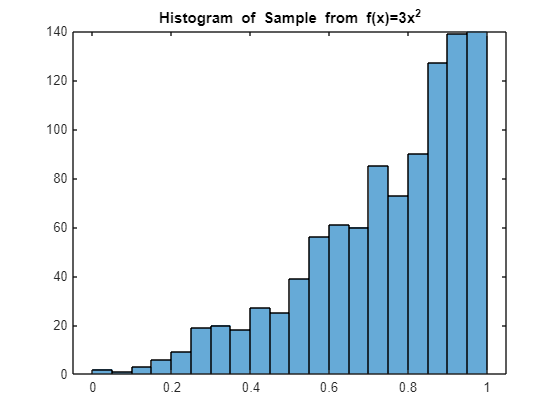

n=1000;
U=rand(n,1);
% Inverse transform
X=U.^(1/3);
histogram(X,20);
title('Histogram of Sample from f(x)=3x^2');

% Sample mean and variance
sample_mean = mean(X)

sample_mean = 0.7461

sample_variance = var(X)

sample_variance = 0.0411

7. Generate a sample of size 500 from a population with probability mass function, f(5)=0.2, f(9)=0.1,  f(12)=0.4, f(15)=0.3.

n=500;
U=rand(n,1);
%preallocate
X=zeros(n,1);
% Apply inverse transform
for i=1:n
    if U(i)<0.2
        X(i)=5;
    elseif U(i)<0.3
        X(i)=9;
    elseif U(i)<0.7
        X(i)=12;
    else
        X(i)=15;
    end
end
X

X =      5
    12
     9
     5
     5
    15
    15
     5
     5
    15


tabulate(X)

  Value    Count   Percent
      1        0      0.00%
      2        0      0.00%
      3        0      0.00%
      4        0      0.00%
      5       92     18.40%
      6        0      0.00%
      7        0      0.00%
      8        0      0.00%
      9       48      9.60%
     10        0      0.00%
     11        0      0.00%
     12      199     39.80%
     13        0      0.00%
     14        0      0.00%
     15      161     32.20%


%vectorized way of doing the same:
n=500;
U=rand(n,1);
X=zeros(n,1);
X(U<0.2)=5;
X(U>=0.2 & U<0.3)=9;
X(U>=0.3 & U<0.7)=12;
X(U>=0.7)=15;
X

X =     12
    15
    15
     5
    12
    12
    12
     9
    12
    15


tabulate(X)

  Value    Count   Percent
      1        0      0.00%
      2        0      0.00%
      3        0      0.00%
      4        0      0.00%
      5      102     20.40%
      6        0      0.00%
      7        0      0.00%
      8        0      0.00%
      9       53     10.60%
     10        0      0.00%
     11        0      0.00%
     12      204     40.80%
     13        0      0.00%
     14        0      0.00%
     15      141     28.20%


8. Generate a sample of size 100 from a binomial population with n=3 and p=0.2. Show the histogram with  probability. 

n=3;
p=0.2;
y=0:n;
f=pdf('bino',y,n,p);
F=cdf('bino',y,n,p);
x=rand(100,1);
for i=1:100
    if x(i)<=F(1)
        x(i)=y(1);
    elseif x(i)<=F(2)
        x(i)=y(2);
    elseif x(i)<=F(3)
        x(i)=y(3);
    else
        x(i)=y(4);
    end
end
x,histogram(x,'normalization','probability')

x =      1
     2
     1
     0
     0
     0
     2
     0
     0
     0


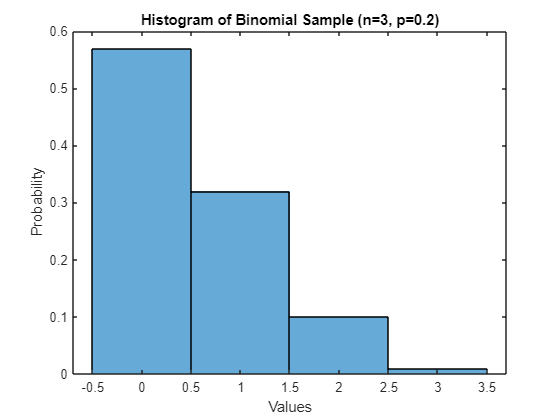

xlabel('Values')
ylabel('Probability')
title('Histogram of Binomial Sample (n=3, p=0.2)');

tabulate(x)

  Value    Count   Percent
      0       57     57.00%
      1       32     32.00%
      2       10     10.00%
      3        1      1.00%


9. Generate a sample of size 1000 from a binomial population with n=12 and p=0.25. Show the histogram  with probability. Evaluate the mean and variance of this sample and compare with the mean and  variance of the actual population.

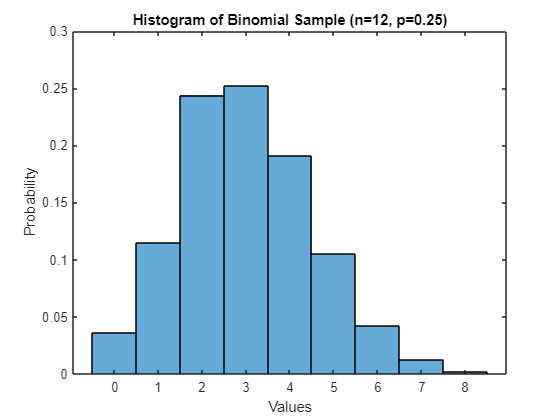

n=12;
p=0.25;
% Generate sample of size 1000
x = binornd(n, p, [1000, 1]);
% Histogram with probability normalization
histogram(x, 'Normalization', 'probability')
xlabel('Values')
ylabel('Probability')
title('Histogram of Binomial Sample (n=12, p=0.25)')

% Sample mean and variance
sample_mean = mean(x);
sample_variance = var(x);
% Theoretical (population) mean and variance
theoretical_mean = n * p;
theoretical_variance = n * p * (1 - p);

% Display results
fprintf('Sample Mean = %.4f\n', sample_mean);

Sample Mean = 3.0070


fprintf('Sample Variance = %.4f\n', sample_variance);

Sample Variance = 2.2772


fprintf('Theoretical Mean = %.4f\n', theoretical_mean);

Theoretical Mean = 3.0000


fprintf('Theoretical Variance = %.4f\n', theoretical_variance);

Theoretical Variance = 2.2500


10. Try to come up with another method to find the value of ‘pi’ using random number generation and  probability.

N=100000;
x=rand(N,1);
y=rand(N,1);
rsq=x.^2+y.^2;
z=(rsq<=1);
pivalue=4*sum(z)/N

pivalue = 3.1350